Open an hdf5 file for a play


h5disp("/Volumes/Data/laion/public-queries-10k-pca32v2.h5");

HDF5 public-queries-10k-pca32v2.h5 
Group '/' 
    Dataset 'pca32' 
        Size:  32x10000
        MaxSize:  32x10000
        Datatype:   H5T_IEEE_F32LE (single)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


data32 = h5read("/Volumes/Data/laion/public-queries-10k-pca32v2.h5","/pca32");
data32 = data32';

and the big dim data...


h5disp("/Volumes/Data/laion/public-queries-10k-clip768v2.h5");

HDF5 public-queries-10k-clip768v2.h5 
Group '/' 
    Dataset 'emb' 
        Size:  768x10000
        MaxSize:  768x10000
        Datatype:   H5T_IEEE_F32LE (single)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


data768 = h5read("/Volumes/Data/laion/public-queries-10k-clip768v2.h5","/emb");
data768 = data768';


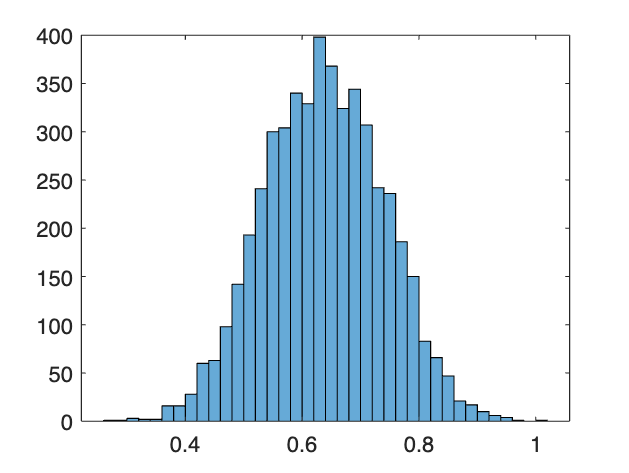


lotsOfDists = pdist(data32(1:100,:));
histogram(lotsOfDists);

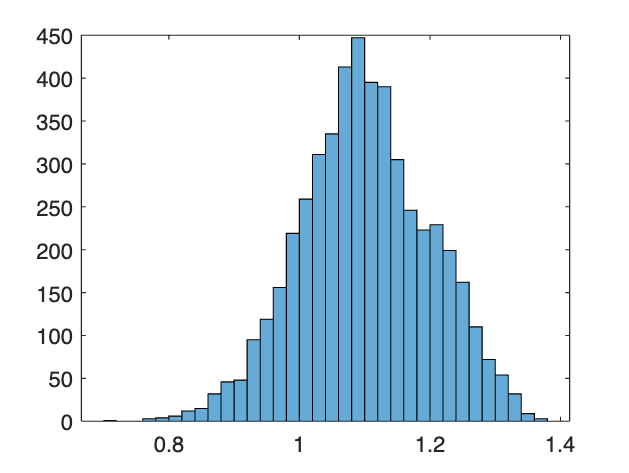


lotsOfDists = pdist(data768(1:100,:));
histogram(lotsOfDists);

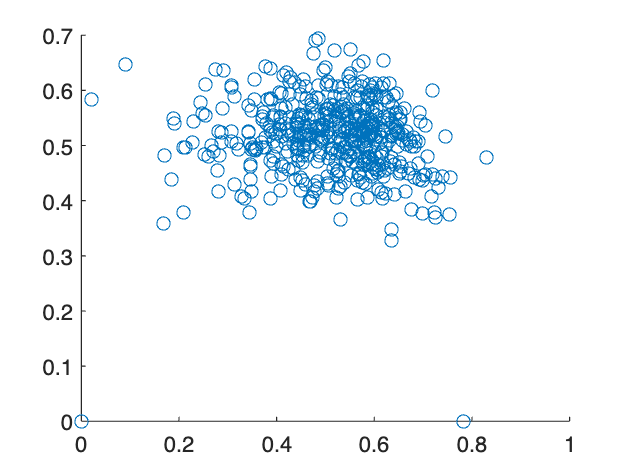


data = data32;

simp = NsimpProjection(data(10:11,:),2,@euc);
coords = zeros(500,2);
for i = 1 : 500
    coords(i,:) = simp.project(data(i,:));
end

scatter(coords(:,1),coords(:,2));

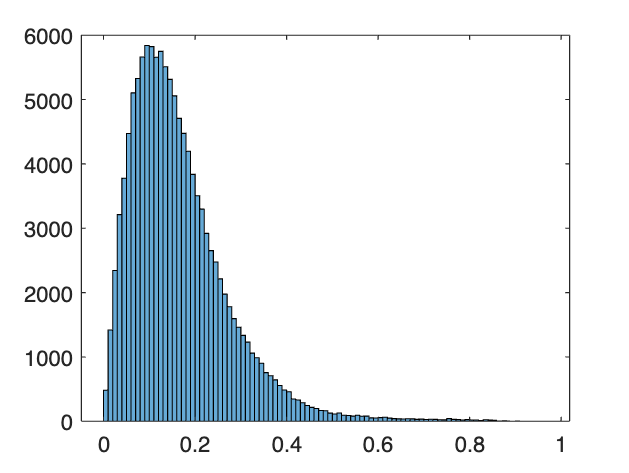


histogram(pdist(coords));

gold standard


h5disp("/Volumes/Data/laion/laion2B-en-public-gold-standard-v2-100K.h5");


